%calculating the mean first passage time analytically/numerically 
%to investigate effect of invader-substrate mismatch position on RNA/DNA
%toehold exchange kinetics including spontaneous incumbent dissociation

b = 20 %define branch migration domain length

b = 20

g = 5 %define invader toehold length

g = 5

g2 = 2 %define incumbent toehold length 

g2 = 2


bg2 = b + g2 %define branch migration domain + incumbent toehold length

bg2 = 22


R = 1.987/1000 % universal gas constant in kcal/K/mol 

R = 0.0020

temp = 298.15 %temperature in K

temp = 298.1500

%free energy parameters
dGassoc = 2.6*R*temp

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGrd = -1.5*R*temp

dGrd = -0.8886

dGp = 3.6*R*temp

dGp = 2.1327

dGmm = 9.5*R*temp

dGmm = 5.6280

dGbm = 7.4*R*temp 

dGbm = 4.3839

%absolute rate constant
k_bp = 5.4*10^7

k_bp = 54000000

k_eff = zeros(1,20)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = zeros(1, 20)

first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound = zeros(1, 20)

prob_unbound =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


k_eff_perf = zeros(1, 20)

k_eff_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time_perf = zeros(1, 20)

first_pass_time_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound_perf = zeros(1, 20)

prob_unbound_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through mismatch positions
for m = 1:20
    
    %define forward and reverse transition rates
    k_AA = 0;
    k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
    k_B1A = k_bp * exp((dGbp + dGrd)/(R*temp))
    k_BC1ij = k_bp;
    k_BC1ji = k_bp * exp((dGbp + dGrd)/(R*temp))
    k_C1f = k_bp * exp(-(dGbm + dGp)/(R*temp))
    k_Cf = k_bp * exp(-dGbm/(R*temp))
    k_Cr = k_bp * exp(-(dGbm - dGrd)/(R*temp))
    k_Crm = k_bp* exp((dGmm - dGbm + dGrd)/(R*temp)) %I have added the + dGrd
    k_Crm_end = k_bp * exp((dGmm - dGbm - dGp + dGrd)/(R*temp)) %I have added the + dGrd
    k_DC = k_bp * exp(-(dGbm + dGp - dGrd)/(R*temp))
    k_DEij = k_bp * exp(dGbp/(R*temp));
    k_DEji = k_bp;
    k_EF = k_bp*exp(dGbp/(R*temp));
    k_FE = 0
    k_FF = 1    
    
    %create arrays of forward and reverse transition rates for
    %mismatch-free system
    Kf_perf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
    Kb_perf = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
        
    if m == b
        %create arrays of forward and reverse transition rates for mismatch
        %system
        Kf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
        Kb = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
        Kb(g2 + b - m + 1) = k_Crm_end
        
        %define spontaneous incumbent dissociation rates
        Koff = [repmat(0, [1, g2+1])]; 
        for n = g2+ 1:bg2-1
            Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
        end
        Koff = horzcat(Koff, [repmat(0, [1, g+1])])
        
    else
        
        %create arrays of forward and reverse transition rates for mismatch
        %system
        Kf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
        Kb = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
        Kb(g2 + b - m + 1) = k_Crm
        
        %define spontaneous incumbent dissociation rates
        Koff = [repmat(0, [1, g2+1])]; 
        for n = g2+ 1:bg2-1
            Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
        end
        Koff = horzcat(Koff, [repmat(0, [1, g+1])])
        
    end
    
    Pn_jN_1 = zeros(1,numel(Kf))
    jn_jN_1 = zeros(1,numel(Kf))
    Pn_jN_1 (1) = 0;
    jn_jN_1 (1) = 1;
        
    %calculate flux between each state for mismatch system
    for Pn = 2:numel(Kf)
        Pn_jN_1(Pn)  = 1/Kf(Pn) * jn_jN_1 (Pn-1) + (Kb(Pn-1)/Kf(Pn))*Pn_jN_1(Pn-1);
        jn_jN_1(Pn) = jn_jN_1(Pn-1) + Koff(Pn) * Pn_jN_1(Pn);
    end
        
    Pn_jN_1_perf = zeros(1,numel(Kf_perf))
    jn_jN_1_perf = zeros(1,numel(Kf_perf))
    Pn_jN_1_perf (1) = 0;
    jn_jN_1_perf (1) = 1;
        
    %calculate flux between each state for mismatch-free system
    for Pn = 2:numel(Kf_perf)
        Pn_jN_1_perf(Pn)  = 1/Kf_perf(Pn) * jn_jN_1_perf (Pn-1) + (Kb_perf(Pn-1)/Kf_perf(Pn))*Pn_jN_1_perf(Pn-1);
        jn_jN_1_perf(Pn) = jn_jN_1_perf(Pn-1) + Koff(Pn) * Pn_jN_1_perf(Pn);
    end
    
    first_pass_time (m) = (1/jn_jN_1(end-1))*sum(Pn_jN_1) %first passage time for mismatch system
    k_eff (m) = 1/(first_pass_time (m)*(5*10^-8));%effective rate constant for mismatch system
    prob_unbound(m) = Pn_jN_1(end)/sum(Pn_jN_1)%prob of being in unbound state for mismatch system
    
    first_pass_time_perf (m) = (1/jn_jN_1_perf(end-1))*sum(Pn_jN_1_perf) %first passage time for mismatch-free system
    k_eff_perf (m) = 1/(first_pass_time_perf (m)*(5*10^-8));%effective rate constant for mismatch-free system
    prob_unbound_perf(m) = Pn_jN_1_perf(end)/sum(Pn_jN_1_perf)%prob of being in unbound state for mismatch-free system
end

k_AB1 = 0.2005

k_B1A = 9.6946e+05

k_BC1ji = 9.6946e+05

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 7.3650e+03

k_Crm = 9.8394e+07

k_Crm_end = 2.6885e+06

k_DC = 201.2393

k_FE = 0

k_FF = 1

Kf_perf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf = 	1.0e+07 *

         0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kb = 	1.0e+07 *

         0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    9.8394    0.0969    0.0969    0.0969    0.0969    0.0969         0


Koff = 	1.0e+04 *

         0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    11.5491         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.6247         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     5.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9996         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 9.6946e+05

k_BC1ji = 9.6946e+05

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 7.3650e+03

k_Crm = 9.8394e+07

k_Crm_end = 2.6885e+06

k_DC = 201.2393

k_FE = 0

k_FF = 1

Kf_perf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf = 	1.0e+07 *

         0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kb = 	1.0e+07 *

         0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    9.8394    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Koff = 	1.0e+04 *

         0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    11.5491    6.6402         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.6247    0.8366         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     5.0806    5.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9996    0.9996         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 9.6946e+05

k_BC1ji = 9.6946e+05

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 7.3650e+03

k_Crm = 9.8394e+07

k_Crm_end = 2.6885e+06

k_DC = 201.2393

k_FE = 0

k_FF = 1

Kf_perf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf = 	1.0e+07 *

         0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kb = 	1.0e+07 *

         0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    9.8394    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Koff = 	1.0e+04 *

         0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    11.5491    6.6402    5.5448         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.6247    0.8366    0.9351         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     5.0806    5.0806    5.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9996    0.9996    0.9996         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 9.6946e+05

k_BC1ji = 9.6946e+05

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 7.3650e+03

k_Crm = 9.8394e+07

k_Crm_end = 2.6885e+06

k_DC = 201.2393

k_FE = 0

k_FF = 1

Kf_perf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf = 	1.0e+07 *

         0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kf = 	1.0e+07 *

    0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kb =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    9.8394    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    11.5491    6.6402    5.5448    5.3004         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.6247    0.8366    0.9351    0.9626         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     5.0806    5.0806    5.0806    5.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9996    0.9996    0.9996    0.9996         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 9.6946e+05

k_BC1ji = 9.6946e+05

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 7.3650e+03

k_Crm = 9.8394e+07

k_Crm_end = 2.6885e+06

k_DC = 201.2393

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kb =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    9.8394    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    11.5491    6.6402    5.5448    5.3004    5.2459         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.6247    0.8366    0.9351    0.9626    0.9691         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     5.0806    5.0806    5.0806    5.0806    5.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9996    0.9996    0.9996    0.9996    0.9996         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 9.6946e+05

k_BC1ji = 9.6946e+05

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 7.3650e+03

k_Crm = 9.8394e+07

k_Crm_end = 2.6885e+06

k_DC = 201.2393

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kb =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    9.8394    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    11.5491    6.6402    5.5448    5.3004    5.2459    5.2337         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.6247    0.8366    0.9351    0.9626    0.9691    0.9706         0         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     5.0806    5.0806    5.0806    5.0806    5.0806    5.0806         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9996    0.9996    0.9996    0.9996    0.9996    0.9996         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 9.6946e+05

k_BC1ji = 9.6946e+05

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 7.3650e+03

k_Crm = 9.8394e+07

k_Crm_end = 2.6885e+06

k_DC = 201.2393

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kb =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    9.8394    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    11.5491    6.6402    5.5448    5.3004    5.2459    5.2337    5.2310         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.6247    0.8366    0.9351    0.9626    0.9691    0.9706    0.9709         0         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 9.6946e+05

k_BC1ji = 9.6946e+05

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 7.3650e+03

k_Crm = 9.8394e+07

k_Crm_end = 2.6885e+06

k_DC = 201.2393

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kb =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    9.8394    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    11.5491    6.6402    5.5448    5.3004    5.2459    5.2337    5.2310    5.2304         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.6247    0.8366    0.9351    0.9626    0.9691    0.9706    0.9709    0.9710         0         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 9.6946e+05

k_BC1ji = 9.6946e+05

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 7.3650e+03

k_Crm = 9.8394e+07

k_Crm_end = 2.6885e+06

k_DC = 201.2393

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kb =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    9.8394    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    11.5491    6.6402    5.5448    5.3004    5.2459    5.2337    5.2310    5.2304    5.2303         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.6247    0.8366    0.9351    0.9626    0.9691    0.9706    0.9709    0.9710    0.9710         0         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806         0         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 9.6946e+05

k_BC1ji = 9.6946e+05

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 7.3650e+03

k_Crm = 9.8394e+07

k_Crm_end = 2.6885e+06

k_DC = 201.2393

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kb =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    9.8394    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    11.5491    6.6402    5.5448    5.3004    5.2459    5.2337    5.2310    5.2304    5.2303    5.2302         0         0         0         0         0         0         0         0         0         0


prob_unbound =     0.6247    0.8366    0.9351    0.9626    0.9691    0.9706    0.9709    0.9710    0.9710    0.9710         0         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806         0         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 9.6946e+05

k_BC1ji = 9.6946e+05

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 7.3650e+03

k_Crm = 9.8394e+07

k_Crm_end = 2.6885e+06

k_DC = 201.2393

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kb =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    9.8394    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    11.5491    6.6402    5.5448    5.3004    5.2459    5.2337    5.2310    5.2304    5.2303    5.2302    5.2302         0         0         0         0         0         0         0         0         0


prob_unbound =     0.6247    0.8366    0.9351    0.9626    0.9691    0.9706    0.9709    0.9710    0.9710    0.9710    0.9710         0         0         0         0         0         0         0         0         0


first_pass_time_perf =     5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806         0         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 9.6946e+05

k_BC1ji = 9.6946e+05

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 7.3650e+03

k_Crm = 9.8394e+07

k_Crm_end = 2.6885e+06

k_DC = 201.2393

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kb =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    9.8394    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    11.5491    6.6402    5.5448    5.3004    5.2459    5.2337    5.2310    5.2304    5.2303    5.2302    5.2302    5.2302         0         0         0         0         0         0         0         0


prob_unbound =     0.6247    0.8366    0.9351    0.9626    0.9691    0.9706    0.9709    0.9710    0.9710    0.9710    0.9710    0.9710         0         0         0         0         0         0         0         0


first_pass_time_perf =     5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806         0         0         0         0         0         0         0         0


prob_unbound_perf =     0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 9.6946e+05

k_BC1ji = 9.6946e+05

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 7.3650e+03

k_Crm = 9.8394e+07

k_Crm_end = 2.6885e+06

k_DC = 201.2393

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kb =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    9.8394    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    11.5491    6.6402    5.5448    5.3004    5.2459    5.2337    5.2310    5.2304    5.2303    5.2302    5.2302    5.2302    5.2302         0         0         0         0         0         0         0


prob_unbound =     0.6247    0.8366    0.9351    0.9626    0.9691    0.9706    0.9709    0.9710    0.9710    0.9710    0.9710    0.9710    0.9710         0         0         0         0         0         0         0


first_pass_time_perf =     5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806         0         0         0         0         0         0         0


prob_unbound_perf =     0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 9.6946e+05

k_BC1ji = 9.6946e+05

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 7.3650e+03

k_Crm = 9.8394e+07

k_Crm_end = 2.6885e+06

k_DC = 201.2393

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kb =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    9.8394    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    11.5491    6.6402    5.5448    5.3004    5.2459    5.2337    5.2310    5.2304    5.2303    5.2302    5.2302    5.2302    5.2302    5.2300         0         0         0         0         0         0


prob_unbound =     0.6247    0.8366    0.9351    0.9626    0.9691    0.9706    0.9709    0.9710    0.9710    0.9710    0.9710    0.9710    0.9710    0.9710         0         0         0         0         0         0


first_pass_time_perf =     5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806         0         0         0         0         0         0


prob_unbound_perf =     0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 9.6946e+05

k_BC1ji = 9.6946e+05

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 7.3650e+03

k_Crm = 9.8394e+07

k_Crm_end = 2.6885e+06

k_DC = 201.2393

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kb =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    9.8394    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    11.5491    6.6402    5.5448    5.3004    5.2459    5.2337    5.2310    5.2304    5.2303    5.2302    5.2302    5.2302    5.2302    5.2300    5.2282         0         0         0         0         0


prob_unbound =     0.6247    0.8366    0.9351    0.9626    0.9691    0.9706    0.9709    0.9710    0.9710    0.9710    0.9710    0.9710    0.9710    0.9710    0.9714         0         0         0         0         0


first_pass_time_perf =     5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806         0         0         0         0         0


prob_unbound_perf =     0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 9.6946e+05

k_BC1ji = 9.6946e+05

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 7.3650e+03

k_Crm = 9.8394e+07

k_Crm_end = 2.6885e+06

k_DC = 201.2393

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kb =          0    5.4000    0.0000    0.0007    0.0007    0.0007    9.8394    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    11.5491    6.6402    5.5448    5.3004    5.2459    5.2337    5.2310    5.2304    5.2303    5.2302    5.2302    5.2302    5.2302    5.2300    5.2282    5.2106         0         0         0         0


prob_unbound =     0.6247    0.8366    0.9351    0.9626    0.9691    0.9706    0.9709    0.9710    0.9710    0.9710    0.9710    0.9710    0.9710    0.9710    0.9714    0.9746         0         0         0         0


first_pass_time_perf =     5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806         0         0         0         0


prob_unbound_perf =     0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996         0         0         0         0


k_AB1 = 0.2005

k_B1A = 9.6946e+05

k_BC1ji = 9.6946e+05

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 7.3650e+03

k_Crm = 9.8394e+07

k_Crm_end = 2.6885e+06

k_DC = 201.2393

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kb =          0    5.4000    0.0000    0.0007    0.0007    9.8394    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    11.5491    6.6402    5.5448    5.3004    5.2459    5.2337    5.2310    5.2304    5.2303    5.2302    5.2302    5.2302    5.2302    5.2300    5.2282    5.2106    5.1342         0         0         0


prob_unbound =     0.6247    0.8366    0.9351    0.9626    0.9691    0.9706    0.9709    0.9710    0.9710    0.9710    0.9710    0.9710    0.9710    0.9710    0.9714    0.9746    0.9891         0         0         0


first_pass_time_perf =     5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806         0         0         0


prob_unbound_perf =     0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996         0         0         0


k_AB1 = 0.2005

k_B1A = 9.6946e+05

k_BC1ji = 9.6946e+05

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 7.3650e+03

k_Crm = 9.8394e+07

k_Crm_end = 2.6885e+06

k_DC = 201.2393

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kb =          0    5.4000    0.0000    0.0007    9.8394    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    11.5491    6.6402    5.5448    5.3004    5.2459    5.2337    5.2310    5.2304    5.2303    5.2302    5.2302    5.2302    5.2302    5.2300    5.2282    5.2106    5.1342    5.0871         0         0


prob_unbound =     0.6247    0.8366    0.9351    0.9626    0.9691    0.9706    0.9709    0.9710    0.9710    0.9710    0.9710    0.9710    0.9710    0.9710    0.9714    0.9746    0.9891    0.9983         0         0


first_pass_time_perf =     5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806         0         0


prob_unbound_perf =     0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996         0         0


k_AB1 = 0.2005

k_B1A = 9.6946e+05

k_BC1ji = 9.6946e+05

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 7.3650e+03

k_Crm = 9.8394e+07

k_Crm_end = 2.6885e+06

k_DC = 201.2393

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kb =          0    5.4000    0.0000    9.8394    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    11.5491    6.6402    5.5448    5.3004    5.2459    5.2337    5.2310    5.2304    5.2303    5.2302    5.2302    5.2302    5.2302    5.2300    5.2282    5.2106    5.1342    5.0871    5.0811         0


prob_unbound =     0.6247    0.8366    0.9351    0.9626    0.9691    0.9706    0.9709    0.9710    0.9710    0.9710    0.9710    0.9710    0.9710    0.9710    0.9714    0.9746    0.9891    0.9983    0.9995         0


first_pass_time_perf =     5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806         0


prob_unbound_perf =     0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996         0


k_AB1 = 0.2005

k_B1A = 9.6946e+05

k_BC1ji = 9.6946e+05

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 7.3650e+03

k_Crm = 9.8394e+07

k_Crm_end = 2.6885e+06

k_DC = 201.2393

k_FE = 0

k_FF = 1

Kf_perf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb_perf =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kf =     0.0000    0.4345    0.4345    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0000    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Kb =          0    5.4000    0.2689    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0969    0.0969    0.0969    0.0969    0.0969         0


Koff =          0         0         0    2.8127    0.2263    0.0182    0.0015    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1_perf =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =    11.5491    6.6402    5.5448    5.3004    5.2459    5.2337    5.2310    5.2304    5.2303    5.2302    5.2302    5.2302    5.2302    5.2300    5.2282    5.2106    5.1342    5.0871    5.0811    5.0806


prob_unbound =     0.6247    0.8366    0.9351    0.9626    0.9691    0.9706    0.9709    0.9710    0.9710    0.9710    0.9710    0.9710    0.9710    0.9710    0.9714    0.9746    0.9891    0.9983    0.9995    0.9996


first_pass_time_perf =     5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806    5.0806


prob_unbound_perf =     0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996    0.9996


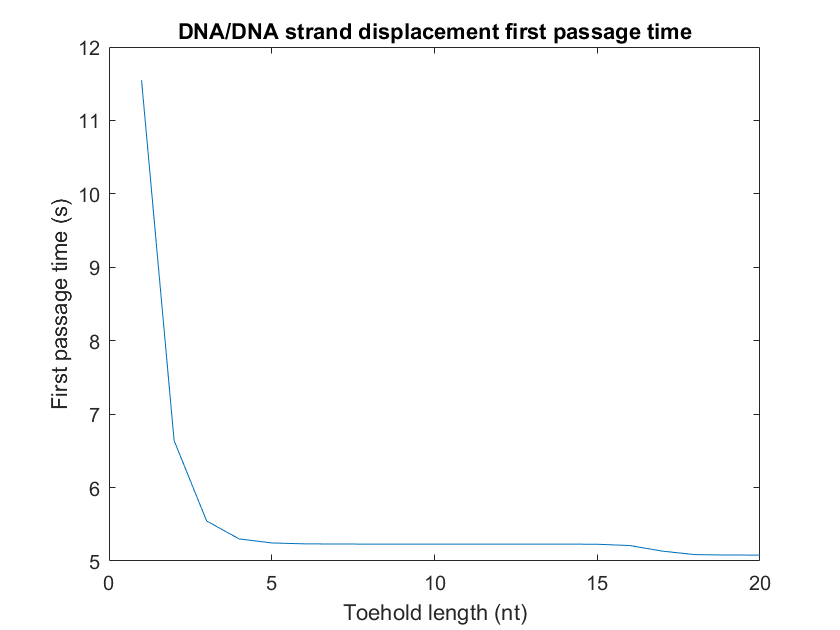

plot(1:20, first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement first passage time')

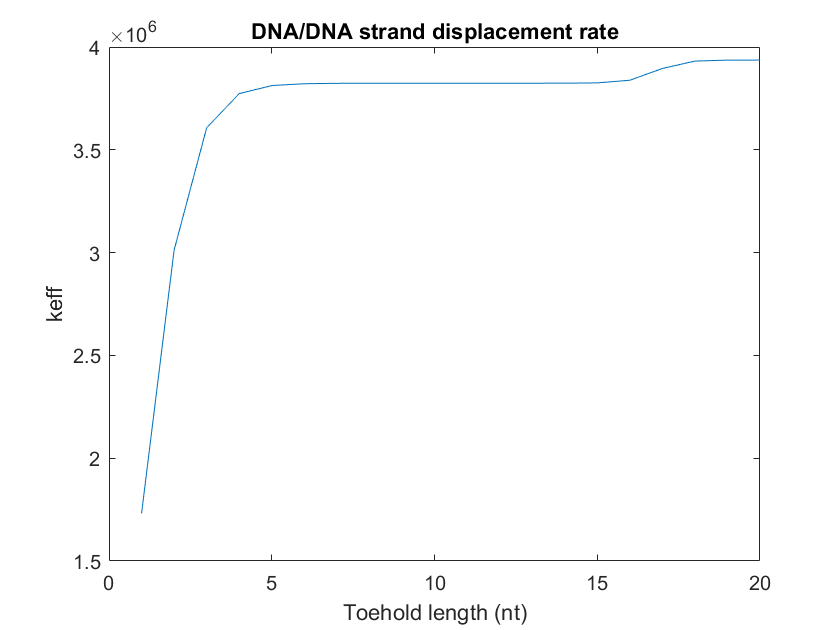


plot(1:20, k_eff)
xlabel('Toehold length (nt)')
ylabel('keff')
title('DNA/DNA strand displacement rate')

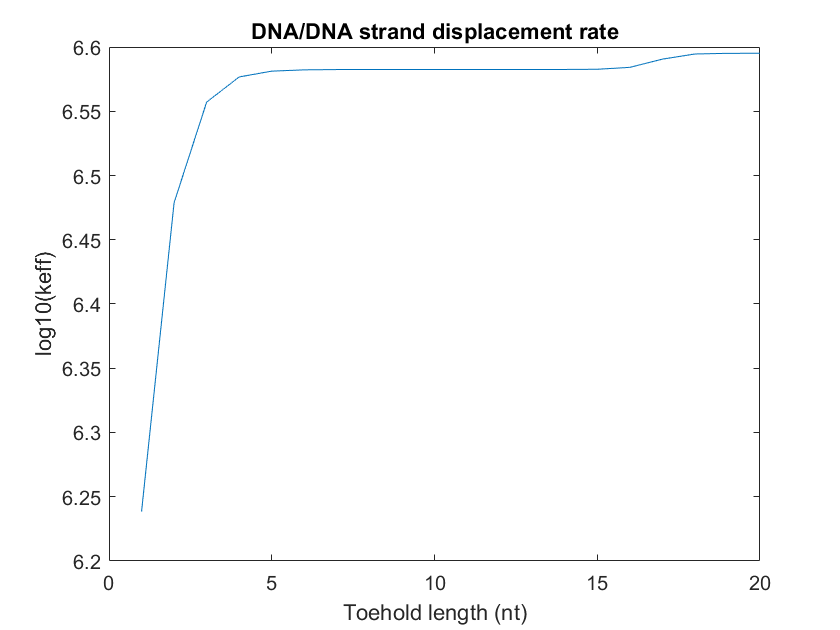


plot(1:20, log10(k_eff))
xlabel('Toehold length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate') 

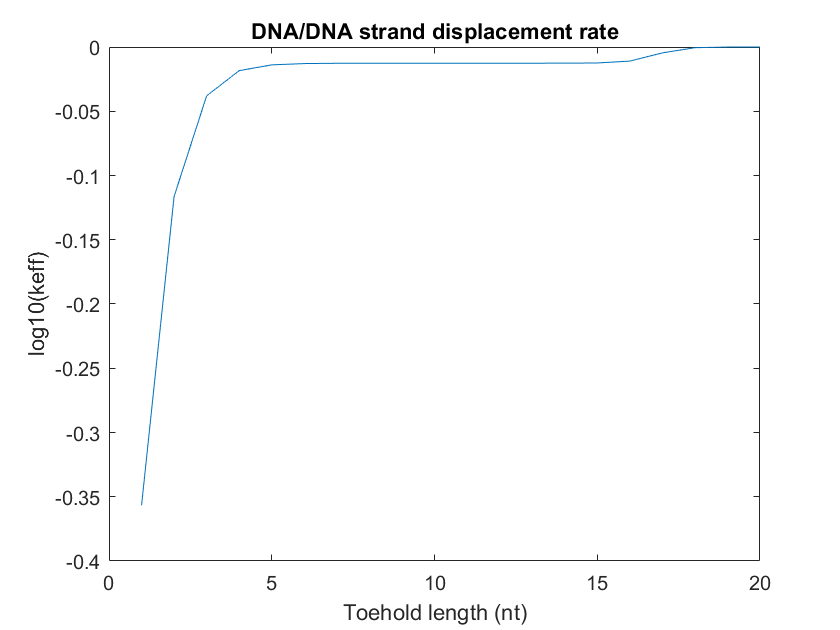


plot(1:20, log10(k_eff./k_eff_perf))
xlabel('Toehold length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate') 